# Expand Example 3.13:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the rectangular pulse shown:

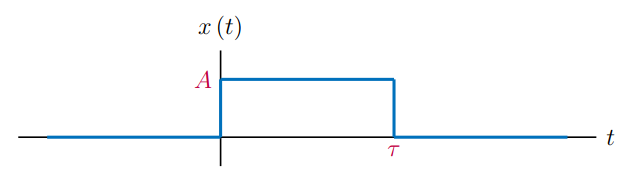

Its Fourier transform was determined as

        $X(f)=A\tau\,\textrm{sinc}(f\tau)\,e^{-j\pi f\tau}$                    (3.144)

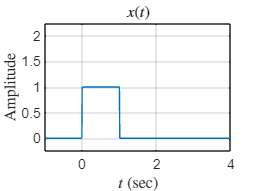

A =   1; % Pulse height
tau = 1; % Pulse width
%
t = [-1:0.01:4];  % Vector of time instants
f = [-6:0.02:6];  % Vector of frequencies
% Compute the signal
xt = A*((t>=0)&(t<=tau));
% Compute the transform
Xf = A*tau*sinc(f*tau).*exp(-j*pi*f*tau);
% Graph the signal
plot(t,xt); grid;
axis([-1,4,-0.25,2.25]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$x(t)$');

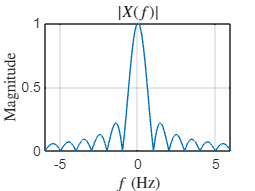

% Graph the transform
plot(f,abs(Xf)); grid;
xlabel('$f$ (Hz)');
ylabel('Magnitude');
title('$|X(f)|$');

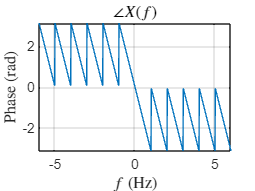

plot(f,angle(Xf)); grid;
axis([-6,6,-pi,pi]);
xlabel('$f$ (Hz)');
ylabel('Phase (rad)');
title('$\angle X(f)$');

set(0,'defaultTextInterpreter','tex');